# Estimation: A Resistor Example

**Author:** Maarten Schoukens - Eindhoven University of Technology

**License and Disclaimer: **BSD 3-Clause "New" or "Revised" License - [link](https://github.com/MaartenSchoukens/SysId-LiveScripts/blob/main/LICENSE)

**Cite As:** M. Schoukens, *SysId LiveScripts - Estimation: A Resistor Example*, Eindhoven University of Technology, [https://github.com/MaartenSchoukens/SysId-LiveScripts,](https://github.com/MaartenSchoukens/SysId-LiveScripts,) 2026.

This code is developed and tested in Matlab R2025b Update 3

clear all % clear workspace
close all % close all figures
clc % clear command window

This livescript introduces the concept of an estimator, illustrates why it is important to reflect on what estimator to use, and discusses some interesting properties and the nature of the resulting estimates. These concepts are illustrated using a resistor estimation problem as a running example. The content of this LiveScript is based on Section 1.2 of *System Identification: A Frequency Domain Approach *by R. Pintelon and J. Schoukens, 2012.

## The Resistor Estimation Problem

### What is an Estimator?

The process of mapping this measured data to a value of the parameter of interest is called an estimator.

### Problem Setting

In many situations we would like to obtain information of a physical quantity or a model parameter staring from measured data. In this case, we have obtained $N$ noisy measurement samples of the voltage $v(k)$ over and the current $i(k)$ flowing through a resistor $R$. The indices $k$ denote the measurement sample. Based on these values we would like to now what the resistor value $R$ is. The relevant physical equation is given by Ohm's law:


$$v=R\;i$$


In this case, the applied current is constant. And the current and voltage have measurement noise on them:


$$i\left(k\right)=i_0 +n_i \left(k\right)$$



$$v\left(k\right)=v_0 +n_v \left(k\right)=R\;i_0 +n_v \left(k\right)$$


The noise is independently distributed zero-mean Gaussian noise with standard deviations $\sigma_i$ and $\sigma_v$ respectively:


$$\begin{array}{l}
n_i \left(k\right)~\mathcal{N}\;\left(0,\sigma_i \right)\\
n_v \left(k\right)~\mathcal{N}\;\left(0,\sigma_v \right)
\end{array}$$


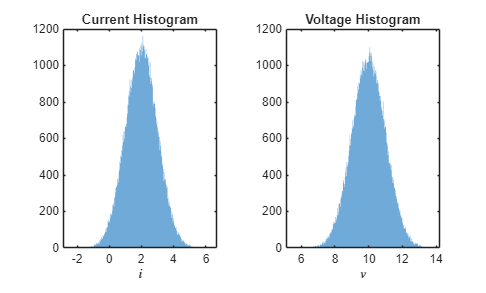

R0 =5; % True underlying resistance value (Ohm)
i0 = 2; % Noiseless constant current (Ampere)
N = 100000; % total number of available measurement samples
sigma_i = 1; % standard deviation of the noise on the current measurements
sigma_v = 1; % standard deviation of the noise on the voltage measurements

v0 = R0*i0; % Noiseless constant voltage (Volt)

i = i0 + sigma_i*randn(N,1);
v = v0 + sigma_v*randn(N,1);

% plot histogram
figure; tiledlayout(1,2); 
nexttile; histogram(i,floor(sqrt(N)),'EdgeAlpha',0); xlabel('$i$','interpreter','latex'); title('Current Histogram')
nexttile; histogram(v,floor(sqrt(N)),'EdgeAlpha',0); xlabel('$v$','interpreter','latex'); title('Voltage Histogram')

## Estimating the Resistor Value

### Considered Estimators

When looking at Ohm's law $v=R\;i$, one can think of multiple ways on how to combine the data into an estimate of $R$. Three at first sight sensible choices are discussed below: averaging the ratios $\frac{v(k)}{i(k)}$, taking the ration of the averages of $v(k)$ and $i(k)$ and performing a least squares regression from current to voltage.

**Averaging the ratios: **$\hat{R}_{SA}(n) = \sum_{k=1}^n \frac{v(k)}{i(k)}$ 

**Ratio of the averages: **$\hat{R}_{EiV}(n) =  \frac{\sum_{k=1}^n v(k)}{\sum_{k=1}^n i(k)}$ 

**Least squares regression from current to voltage: **$\hat{R}_{LS}(n) =  \frac{\sum_{k=1}^n v(k)i(k)}{\sum_{k=1}^n i(k)^2}$

The $n$ argument indicates that the estimator is based on $n$ observations.

### Estimation Results

The three proposed estimators are now applied on the dataset that was generated previously. The estimation result is plotted for a growing number of considered data samples $n$.

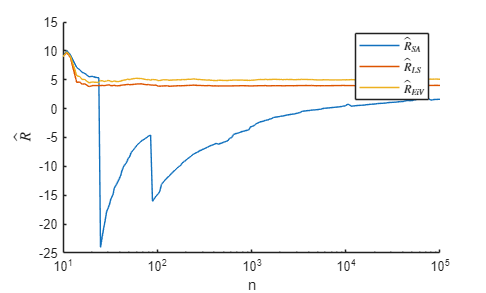

NVector = unique(ceil(logspace(1,log10(N),200))); 
n = length(NVector);

RLS = zeros(n,1);
REiV = zeros(n,1);
RSA = zeros(n,1);
for ii=1:n
    RSA(ii) = mean(v(1:ii)./i(1:ii));
    RLS(ii) = mean(v(1:ii).*i(1:ii))/mean(i(1:ii).*i(1:ii));
    REiV(ii) = mean(v(1:ii))/mean(i(1:ii));
end

%% plotting
figure; hold on; plot(NVector,[RSA RLS REiV])
xlabel('n'); ylabel('$\hat{R}$','interpreter','latex');
legend('$\hat{R}_{SA}$','$\hat{R}_{LS}$','$\hat{R}_{EiV}$','interpreter','latex')
xlim([NVector(1) NVector(end)]);
set(gca, 'XScale', 'log')

**Discussion: **The obtained results give us bad news. While the three proposed estimators seemed sensible at first sight, all three give us different results. Even worse, the $\hat{R}_{SA}$ estimate does not seem to converge (using the standard script settings) for growing values of $n$ while the other two do seem to converge nicely. When comparing to the underlying true resistance value $R_0$ that was used to generate the data, it seems that only $\hat{R}_{EiV}$ converges to this value. These observations motivate further analysis of the proposed estimators in the next section.

## Estimator Analysis

### Monte-Carlo Simulation

To study the statistical properties of the different estimators we run a so-called Monte-Carlo simulation. In this simulation, we run the estimation procedure for $n_{MC}$ independent runs, i.e. the data is generated independently for each run using new random noise samples. We will use the resulting estimates to evaluate some statistical properties of the estimator.

The user can adjust some of the problem settings below to study the impact on the resulting estimates. It is especially interesting to study the effect of the number of samples $N$ used during the estimation and the influence of the noise standard deviations $\sigma_i$ and $\sigma_v$.

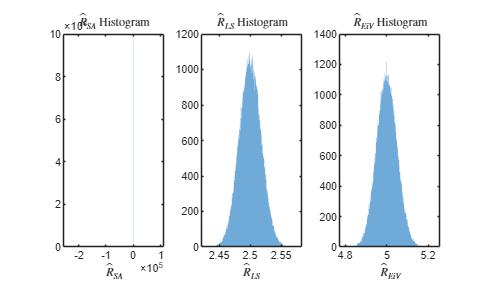

R0 =5; % True underlying resistance value (Ohm)
i0 = 2; % Noiseless constant current (Ampere)
N = 10000; % total number of available measurement samples
sigma_i = 2; % standard deviation of the noise on the current measurements
sigma_v = 0; % standard deviation of the noise on the voltage measurements

v0 = R0*i0; % Noiseless constant voltage (Volt)

nMC = 1e5; % lower this to 1e4 for faster computation
RSAMC = zeros(1,nMC);
RLSMC = zeros(1,nMC);
REiVMC = zeros(1,nMC);
for iMC = 1:nMC
    i = i0 + sigma_i*randn(N,1);
    v = v0 + sigma_v*randn(N,1);

    RSAMC(iMC) = mean(v./i);
    RLSMC(iMC) = v'*i/(i'*i);
    REiVMC(iMC) = mean(v)/mean(i);
end

%% plot distribution
figure; tiledlayout(1,3);
nexttile; histogram(RSAMC,floor(sqrt(nMC)),'EdgeAlpha',0); 
xlabel('$\hat{R}_{SA}$','interpreter','latex'); 
title('$\hat{R}_{SA}$ Histogram','interpreter','latex')
nexttile; histogram(RLSMC,floor(sqrt(nMC)),'EdgeAlpha',0); 
xlabel('$\hat{R}_{LS}$','interpreter','latex'); 
title('$\hat{R}_{LS}$ Histogram','interpreter','latex')
nexttile; histogram(REiVMC,floor(sqrt(nMC)),'EdgeAlpha',0); 
xlabel('$\hat{R}_{EiV}$','interpreter','latex'); 
title('$\hat{R}_{EiV}$ Histogram','interpreter','latex')

**Discussion: **First of all, one can note that the estimate converges to different values for each new Monte Carlo iteration. Since the data is composed of random variables, also the estimate itself will be a random value with a mean and variance! Furthermore, the obtained histograms confirm our observations from our previous discussion. Using the standard slider settings, the $\hat{R}_{SA}$ estimate is even more ill-behaved than what we saw before. Its histogram ranges over a huge scale due to the presence of large outliers. $\hat{R}_{LS}$ estimates are centered around a value that is below the true resistance value $R_0$, while the $\hat{R}_{EiV}$ estimate is centered around this true value $R_0$. 

We will characterize these distributions in terms of their expected value and variance in the next section.

### Estimator Properties

We established above that an estimate is a random variable. A common way to characterize random variables is to look at its mean and variance. Beyond this, it is also interesting to understand if the estimate converges for a growing number of samples to the true underlying parameter value. These concepts are studied using the bias, variance and consistency of an estimator.

#### **Bias**

#### **Variance**

#### **Consistency **

### Cost Function Interpretation

## Further Reading and References

- R. Pintelon and J. Schoukens, *System Identification: A Frequency Domain Approach*, 2nd Edition, Wiley-IEEE Press, 2012.

- J. Schoukens, R. Pintelon and Y. Rolain, *Mastering System Identification in 100 Exercises*, Wiley-IEEE Press, 2012.